# Color differences of 24 patches in four different modes of Spyder X

## OL490 data (ground truth)

### Test target

spd_ol490_24: emulated results by OL490

load('colorchecker_test_result_rift.mat','spd_ol490_24')
spd_ol490_24

spd_ol490_24 = 1×24 cell array
    {[1.4972e-08 2.5929e-08 3.6879e-08 5.0901e-08 4.2836e-08 5.3467e-08 4.7028e-08 5.9818e-08 7.0644e-08 1.1843e-07 1.4277e-07 2.2219e-07 3.0191e-07 3.5057e-07 3.5775e-07 3.3825e-07 3.1435e-07 3.1212e-07 3.0326e-07 2.9248e-07 2.9119e-07 3.3280e-07 3.3253e-07 3.4715e-07 3.6042e-07 3.8128e-07 3.8142e-07 3.8346e-07 3.7168e-07 3.8624e-07 3.9196e-07 4.0358e-07 4.3715e-07 5.6561e-07 7.2445e-07 8.6555e-07 … ]}    {[1.1305e-07 1.3447e-07 1.0049e-07 6.5359e-08 1.5071e-07 1.3031e-07 2.0851e-07 1.7112e-07 1.7692e-07 2.7615e-07 3.8278e-07 5.6575e-07 8.4566e-07 9.6564e-07 9.7230e-07 9.1199e-07 8.8623e-07 8.1264e-07 7.7044e-07 8.0608e-07 8.7205e-07 8.9603e-07 1.0397e-06 1.1664e-06 1.2992e-06 1.3468e-06 1.4043e-06 1.3231e-06 1.3523e-06 1.3240e-06 1.3608e-06 1.3337e-06 1.5003e-06 1.9821e-06 2.5442e-06 2.9489e-06 … ]}    {[8.3598e-08 7.2595e-08 1.3536e-07 1.1292e-07 1.5427e-07 1.5569e-07 1.7237e-07 1.7870e-07 2.3549e-07 3.2891e-07 4.8206e-07 6.8098e-07 9.1624e-07 1.0820e-

%
% reduce from 401 to 41
%
spec_ol490_24 = zeros(24,41);
for i = 1:24
    s = spd_ol490_24{i};
    s = s(1:10:end);
    spec_ol490_24(i,:) = s;
end

spec_ol490_24

spec_ol490_24 = 1.0e-03 *

    0.0000    0.0001    0.0003    0.0004    0.0007    0.0009    0.0064    0.0119    0.0152    0.0115    0.0048    0.0032    0.0044    0.0099    0.0199    0.0213    0.0140    0.0093    0.0048    0.0026    0.0036    0.0053    0.0151    0.0255    0.0305    0.0269    0.0174    0.0127    0.0063    0.0043    0.0029    0.0017    0.0013    0.0012    0.0008    0.0006    0.0006    0.0004    0.0005    0.0002    0.0001
    0.0001    0.0004    0.0009    0.0014    0.0020    0.0033    0.0288    0.0514    0.0555    0.0403    0.0161    0.0154    0.0149    0.0468    0.0756    0.0683    0.0511    0.0374    0.0225    0.0117    0.0115    0.0221    0.0493    0.0819    0.0974    0.0826    0.0566    0.0345    0.0246    0.0151    0.0103    0.0073    0.0037    0.0020    0.0017    0.0012    0.0012    0.0011    0.0009    0.0003    0.0003
    0.0001    0.0005    0.0010    0.0017    0.0028    0.0048    0.0424    0.0768    0.0830    0.0595    0.0243    0.0189    0.0108    0.0296    0.0508 

### Calculate XYZ and LAB

% XYZ is 24x3
XYZ_ol490 = ColorConversionClass.spd2XYZ(spec_ol490_24');
LAB_ol490 = ColorConversionClass.XYZ2lab(XYZ_ol490,XYZ_ol490(19,:));


colorchecker = [
    115 82  68;
    194 150 130;
    98  122 157;
    87  108 67;
    133 128 177;
    103 189 170;

    214 126 44;
    80  91  166;
    193 90  99;
    94  60  108;
    157 188 64;
    224 163 46;

    56  61  150;
    70  148 73;
    175 54  60;
    231 199 31;
    187 86  149;
    8   133 161;

    243 243 242;
    200 200 200;
    160 160 160;
    122 122 121;
    85  85  85;
    52  52  52
    ];

### Generate the spectrum plots

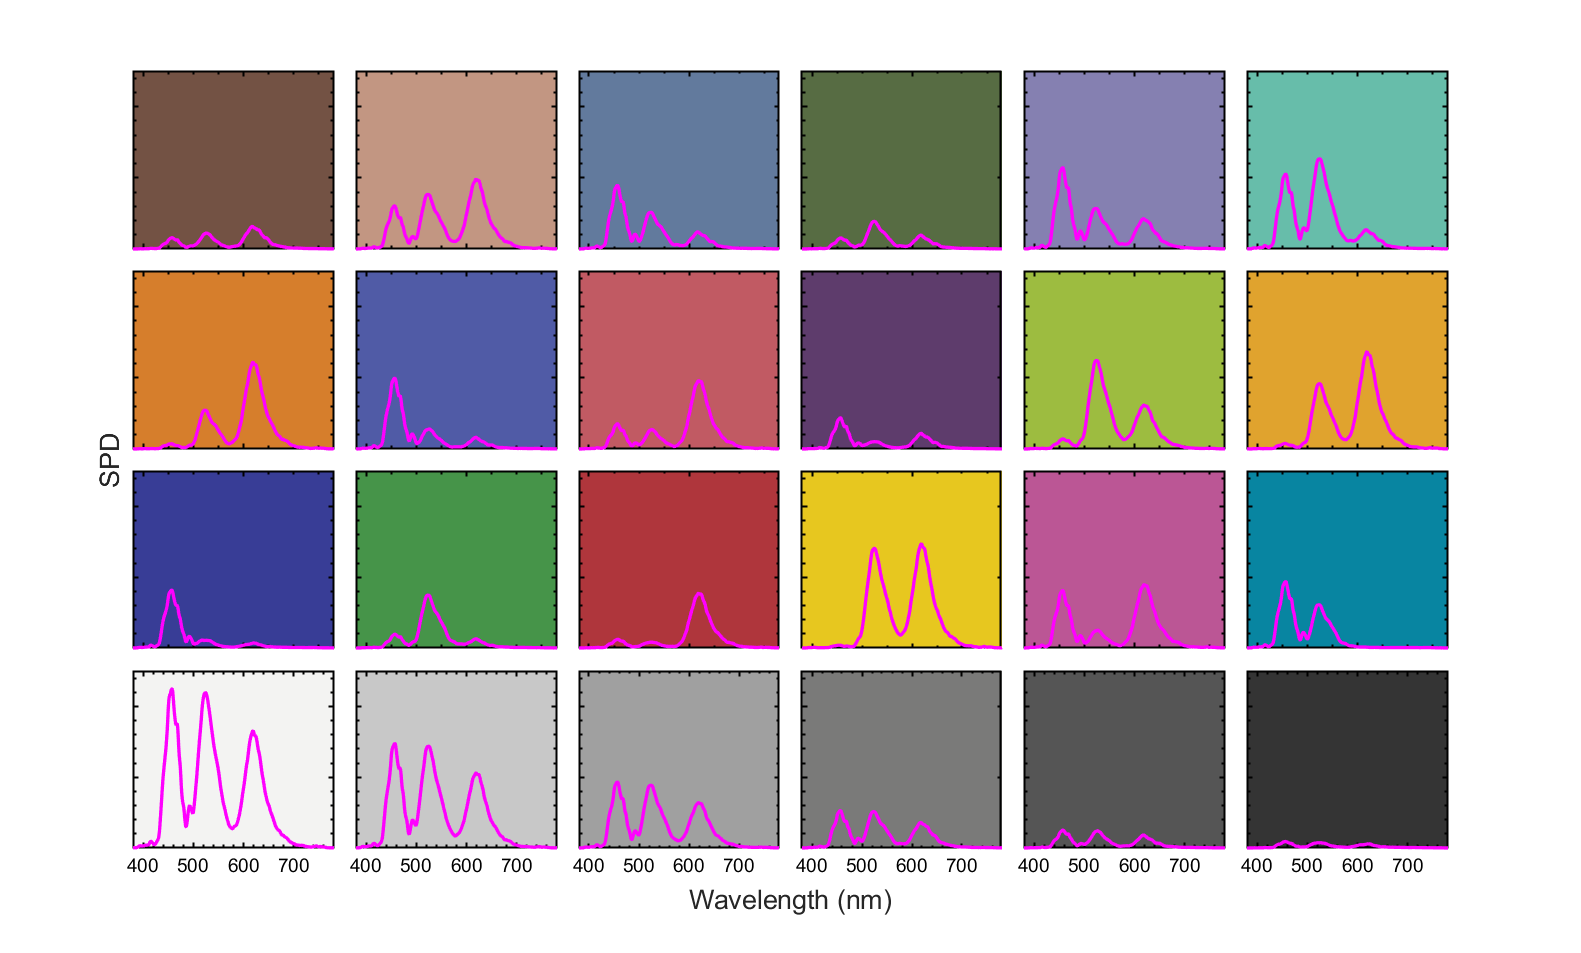

clf
td = tiledlayout(4,6,'TileSpacing','compact');
hg = gcf;
set(hg,'Visible','on');

for idx = 1:24

    haxis = nexttile(idx);
    hold on

    plot(380:780,spd_ol490_24{idx},'m-')
    axis([380 780 0 2.5e-4])

    color_rgb = [0 0.5 1];

    %    title(idx)
    yticklabels({});
    PlotBeautify(haxis)
    legend off

    % change the background color
    set(haxis,'Color',colorchecker(idx,:)/255);

    if idx < 19
        xticklabels({});
    end

    haxis.XAxis.FontSize = 14;

    yticklabels({});

    %     if mod(idx,6)==1
    %         ylabel('SPD');
    %     end

end

td.XLabel.String = 'Wavelength (nm)';
td.XLabel.FontSize = 20;

td.YLabel.String = 'SPD';
td.YLabel.FontSize = 20;

hg.Position = [97 134 1581 953];
saveas(hg,'spectra_on_colorchecker.png')

## Spyder data

X1 Y1 Z1 X2 Y2 Z2 X3 Y3 Z3 X4 Y4 Z4

modename = {'White LED','Standard LED','General','GB LED'};

if 1
    load('spyder_rift','spyder')
else
    load('spyder_rift_calibrated','spyder_calibrated')
    spyder = spyder_calibrated;
end

spyder

spyder =     1.2390    1.1200    0.9020    1.3080    1.1340    0.9390    1.2130    1.1010    0.9060    1.2230    1.0990    0.8990
    4.1430    3.8720    3.1620    4.3750    3.9690    3.2940    4.0550    3.8050    3.1790    4.0580    3.8110    3.1530
    1.8660    2.0410    4.4690    1.9720    2.0990    4.6910    1.8440    2.0140    4.4990    1.8260    1.9970    4.4610
    0.9900    1.4180    0.9120    1.0440    1.4510    0.9530    0.9630    1.3920    0.9180    0.9600    1.3870    0.9110
    2.7450    2.5720    5.6990    2.8810    2.6290    5.9340    2.6950    2.5220    5.7360    2.6890    2.5200    5.6880
    2.8980    4.5200    5.4590    3.0440    4.6200    5.6950    2.8080    4.4040    5.4650    2.7990    4.4040    5.4190
    4.1550    3.3540    0.6160    4.4150    3.4450    0.6410    4.0810    3.3010    0.6130    4.0560    3.2940    0.6100
    1.5000    1.2450    4.9030    1.5650    1.2680    5.1030    1.4780    1.2180    4.9360    1.4760    1.2190    4.8940
    3.3640    2.2330   

### Calculate XYZ and LAB

XYZ_cck = {};
LAB_cck = {};
for mode = 1:4

    colstart = (mode-1)*3 + 1;

    XYZ_cck{mode} = spyder(:,colstart:colstart+2);
    LAB_cck{mode} = ColorConversionClass.XYZ2lab(XYZ_cck{mode},XYZ_cck{mode}(19,:));

end

XYZ_cck

XYZ_cck = 1×4 cell array
    {24×3 double}    {24×3 double}    {24×3 double}    {24×3 double}


LAB_cck

LAB_cck = 1×4 cell array
    {24×3 double}    {24×3 double}    {24×3 double}    {24×3 double}



mode = 3

mode = 3

XYZ_ol490

XYZ_ol490 =     0.0001    0.0001    0.0001
    0.0005    0.0004    0.0003
    0.0002    0.0002    0.0005
    0.0001    0.0002    0.0001
    0.0003    0.0003    0.0006
    0.0003    0.0005    0.0006
    0.0005    0.0004    0.0001
    0.0002    0.0001    0.0005
    0.0004    0.0003    0.0002
    0.0001    0.0001    0.0002


LAB_ol490

LAB_ol490 =    40.0880   16.7570   14.6610
   69.6932   19.1082   18.5241
   52.7994   -1.1106  -26.9090
   44.8186  -23.4151   21.8221
   58.2689   16.0259  -29.9126
   73.8746  -46.2008   -0.9445
   65.7843   37.4230   70.6723
   42.0001   23.4402  -50.0436
   55.3893   56.1857   16.8744
   32.0585   36.8253  -30.1962


XYZ_cck{mode}

ans =     1.2130    1.1010    0.9060
    4.0550    3.8050    3.1790
    1.8440    2.0140    4.4990
    0.9630    1.3920    0.9180
    2.6950    2.5220    5.7360
    2.8080    4.4040    5.4650
    4.0810    3.3010    0.6130
    1.4780    1.2180    4.9360
    3.3150    2.1970    1.8180
    1.0380    0.7030    2.1700


LAB_cck{mode}

ans =    40.5938   15.0031   11.7753
   69.5641   18.3689   17.1448
   53.2139   -0.5966  -27.0467
   45.1955  -24.0060   19.3321
   58.6028   16.3210  -30.1008
   73.8371  -44.6863   -1.2946
   65.6059   36.2556   65.3760
   42.5314   24.2806  -50.0585
   55.2497   54.9180   14.6237
   32.7332   35.7805  -30.7747


## Calculate dE

dEall = zeros(4,24);

for mode = 1:4
    for i = 1:24
        [dE00 dE94 dEab] = ColorConversionClass.LAB2dE(LAB_cck{mode}(i,:)',LAB_ol490(i,:)');
        dE(i) = dE00;
    end
    dEall(mode,:) = dE;
end

dEall

dEall =     1.9721    0.7931    0.4698    1.3934    0.5128    0.6273    1.5236    0.6790    1.1535    1.0831    0.4917    1.0863    1.4199    0.8784    2.3237    0.9346    0.6759    0.8471         0    0.7023    0.6900    0.7220    1.6055    3.1032
    2.1550    0.7425    0.4160    1.3496    0.3669    0.5762    1.6998    0.5016    1.0156    1.0349    0.5136    1.1400    1.1061    0.8489    2.0943    0.8078    0.5835    0.5242         0    0.3374    0.3182    1.0809    1.4860    3.0489
    1.9494    0.7950    0.5692    1.5025    0.3345    0.5478    1.4638    0.7112    1.0959    0.8513    0.7559    1.0324    0.8474    0.8779    2.1779    1.0990    0.5295    0.8363         0    0.3625    0.5815    0.9293    1.6227    3.1015
    1.8634    0.6126    0.4679    1.4670    0.4339    0.3940    1.3642    0.8173    1.0068    0.8953    0.7157    1.0063    0.9747    0.8655    1.3914    1.1416    0.5301    0.8300         0    0.2732    0.4391    1.0892    1.6022    3.0462


dEmean = mean(dEall,2)

dEmean =     1.0703
    0.9895
    1.0239
    0.9678



dEall(3,:)

ans =     1.9494    0.7950    0.5692    1.5025    0.3345    0.5478    1.4638    0.7112    1.0959    0.8513    0.7559    1.0324    0.8474    0.8779    2.1779    1.0990    0.5295    0.8363         0    0.3625    0.5815    0.9293    1.6227    3.1015


### Generate the dE bar charts

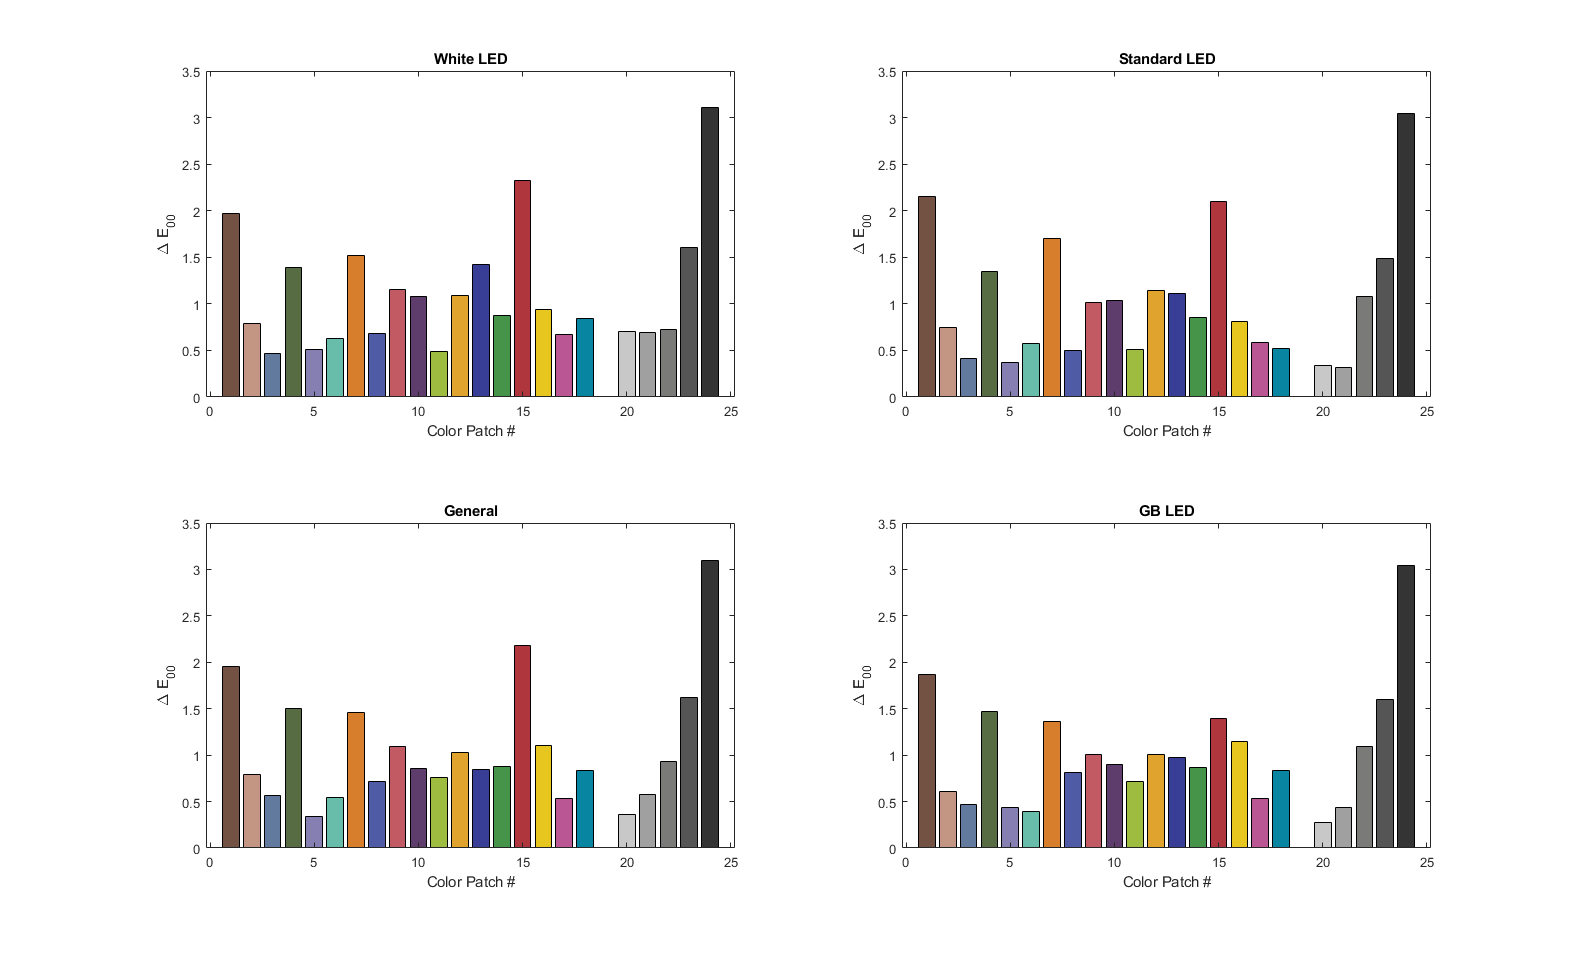

clf
for mode = 1:4

    subplot(2,2,mode)
    hbar = bar(dEall(mode,:),'FaceColor','flat');
    xlabel('Color Patch #')
    ylabel('\Delta E_{00}')
    title(modename{mode})

    for i=1:24
        hbar.CData(i,:) = colorchecker(i,:)/255;
    end
end

saveas(gcf,'compare_dE_2x2.png')

### Generate the dE boxplots

clf
hg = gcf;
set(hg,'Visible','on')
haxis = get(hg,'CurrentAxes');

dEall23 = dEall(:,[1:18 20:24]);                  % remove #19

de_mean = mean(dEall23')

de_mean =     1.1169    1.0325    1.0685    1.0099


de_std = std(dEall23')

de_std =     0.6497    0.6885    0.6532    0.6099


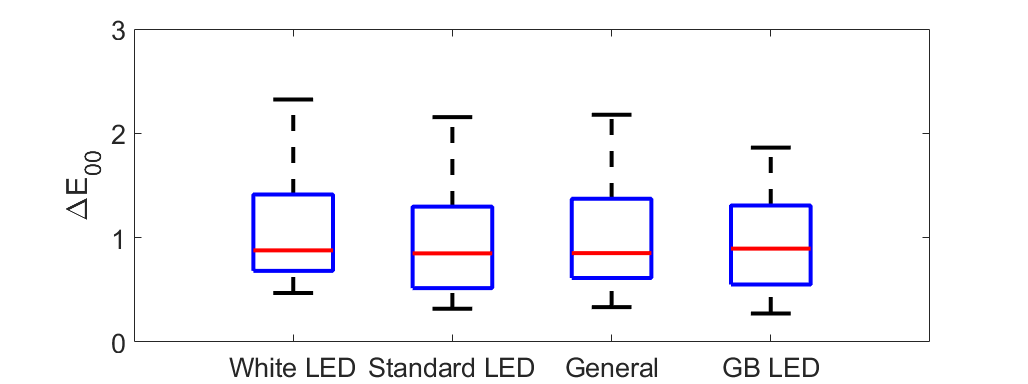


boxplot(dEall23','Notch','off','Labels',modename)
axis([0 5 0 3])
ylabel('\DeltaE_{00}')
set(gca,'XTickLabel',modename,'FontSize',20)

bx = findobj('Tag','boxplot');
set(bx.Children,'LineWidth',3)

hg.Position = [486 514 1028 384];
saveas(gcf,'boxplot_dE.png')

### Compare the dE bar chart for mode General

mode = 3; % general
data = dEall(mode,:);

de_mean = mean(data)

de_mean = 1.0239

de_std = std(data)

de_std = 0.6750

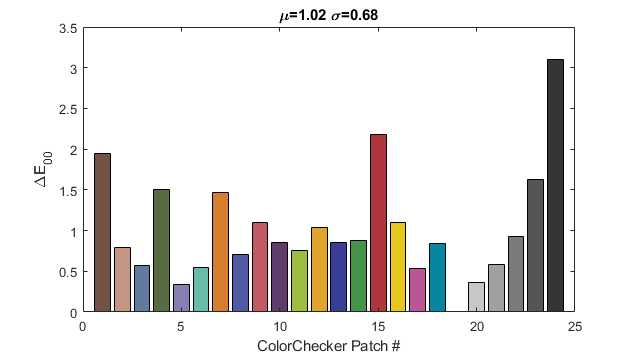


clf
hg = gcf;
set(hg,'Visible','on');
hbar = bar(data','FaceColor','flat');
axis([0 25 0 3.5])
xlabel('ColorChecker Patch #')
ylabel('\DeltaE_{00}')
title(['\mu' sprintf('=%.2f',de_mean) ' \sigma=' sprintf('%.2f',de_std)])

for i=1:24
    hbar.CData(i,:) = colorchecker(i,:)/255;
end

hg.Position = [716 543 635 355];
saveas(hg,'bar_dE.png')

## Does dE correlate with X, Y, or Z?

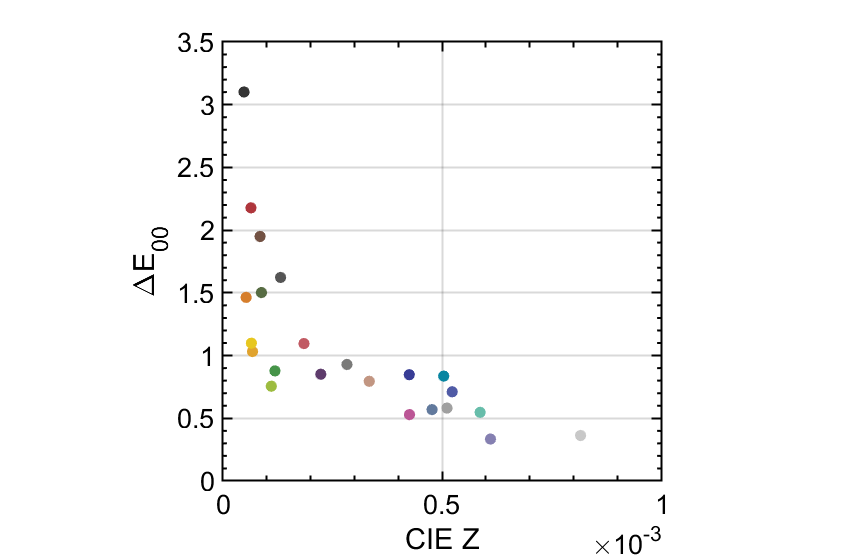

clf
hfig = gcf;
set(hfig,'Visible','on')
haxis = gca;
hold on
for i=[1:18 20:24]
    rgb_color = colorchecker(i,:)/255;
    plot(XYZ_ol490(i,3),data(i),'o','MarkerEdgeColor',rgb_color,'MarkerFaceColor',rgb_color);
end
xlabel('CIE Z')
ylabel('\DeltaE_{00}')
%title('CIE Z')
axis([0 1e-3 0 3.5])
axis square
grid
PlotBeautify(haxis)
legend off
hfig.Position = [640 388 854 560];
saveas(hfig,'dE_vs_CIEZ.png')

## Generate the dE line charts

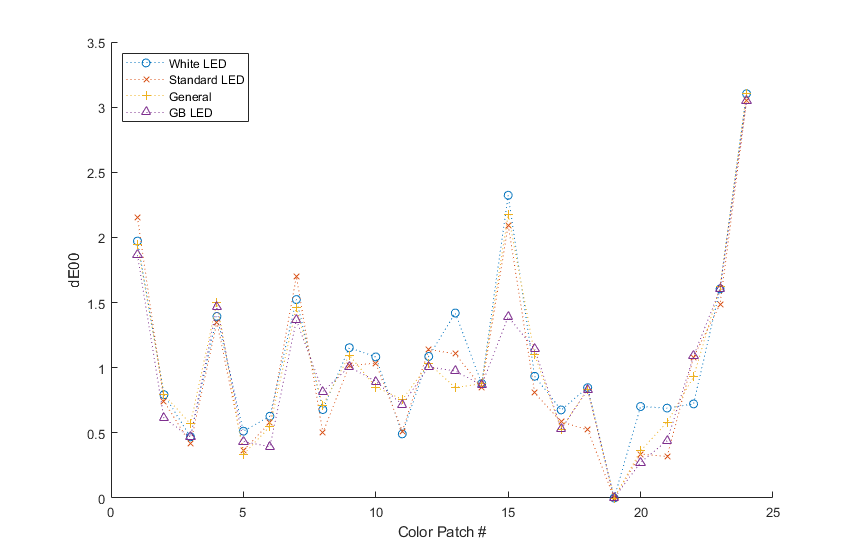

clf
hold on
plot(dEall(1,:),'o:')
plot(dEall(2,:),'x:')
plot(dEall(3,:),'+:')
plot(dEall(4,:),'^:')
xlabel('Color Patch #')
ylabel('dE00')
legend('White LED','Standard LED','General','GB LED')
legend('Location','northwest')


%saveas(gcf,'compare_dE.png')

## 3D view: Comparison of chromaticity in different modes (circle: reference, cross: Spyder X)

% mode = 3
% 
% clf
% set(gca,'Visible','on')
% hold on
% plot3(LAB_cck{mode}(:,2),LAB_cck{mode}(:,3),LAB_cck{mode}(:,1),'x')
% plot3(LAB_ol490(:,2),LAB_ol490(:,3),LAB_ol490(:,1),'o')
% xlabel('CIE a*')
% ylabel('CIE b*')
% zlabel('CIE L*')
% title(mode)

## 2D view: Comparison of chromaticity in different modes (circle: reference, cross: Spyder X)

% clf
% 
% for mode = 1:4
%     subplot(2,2,mode)
%     hold on
%     plot(LAB_cck{mode}(:,2),LAB_cck{mode}(:,3),'x')
%     plot(LAB_ol490(:,2),LAB_ol490(:,3),'o')
%     xlabel('CIE a*')
%     ylabel('CIE b*')
%     % legend('Spyder X','Spectrometer')
%     axis equal
%     title(modename{mode})
% end
% saveas(gcf,'compare CIEab.png')

## Linearity of XYZ

### Generate the linearity plots 

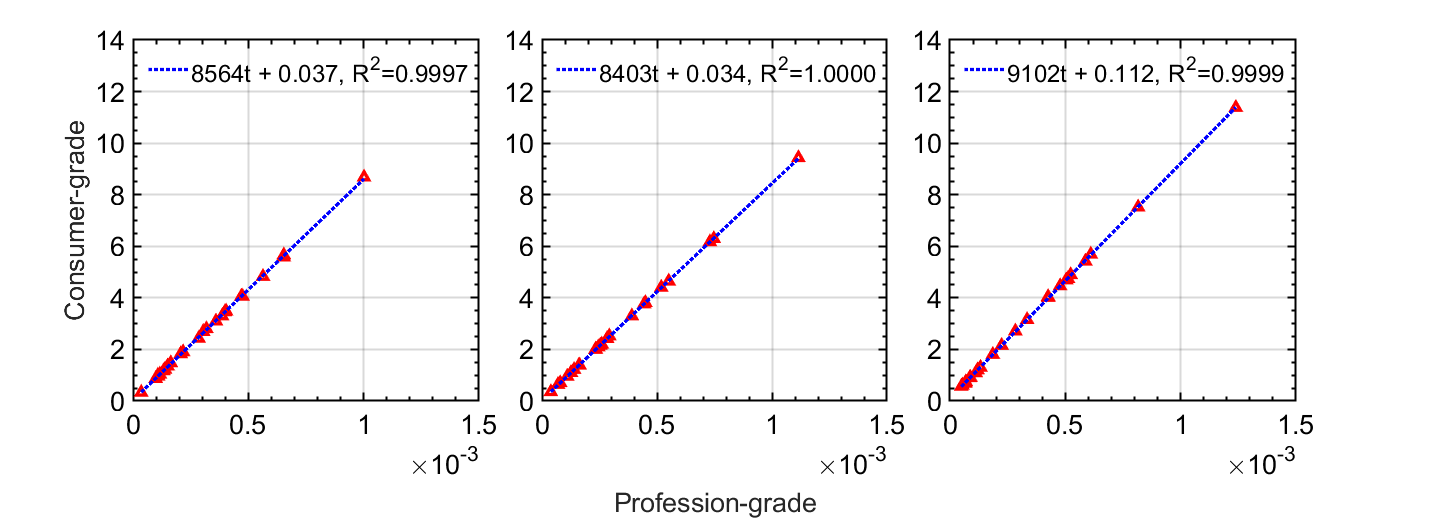

regression_data = {};

for mode = 1:4

    clf
    hfig = gcf;
    set(hfig,'Visible','on')
    td = tiledlayout(1,3,'TileSpacing',"compact");

    i = 1;
    haxis = nexttile(i);
    [poly, rsq, yfit] = linearity_analyzer(XYZ_ol490(:,i),XYZ_cck{mode}(:,i));
    regression_data{mode,i} = {poly, rsq, yfit};
    axis([0 1.5e-3 0 14])
    PlotBeautify(gca)

    i = 2;
    haxis = nexttile(i);
    [poly, rsq, yfit] = linearity_analyzer(XYZ_ol490(:,i),XYZ_cck{mode}(:,i));
    regression_data{mode,i} = {poly, rsq, yfit};
    axis([0 1.5e-3 0 14])
    PlotBeautify(gca)

    i = 3;
    haxis = nexttile(i);
    [poly, rsq, yfit] = linearity_analyzer(XYZ_ol490(:,i),XYZ_cck{mode}(:,i));
    regression_data{mode,i} = {poly, rsq, yfit};
    axis([0 1.5e-3 0 14])
    PlotBeautify(gca)

    td.XLabel.String = 'Profession-grade';
    td.XLabel.FontSize = 20;

    td.YLabel.String = 'Consumer-grade';
    td.YLabel.FontSize = 20;

    hfig.Position = [568 351 1429 528];
    saveas(hfig,sprintf('linearity_plots_mode%d.png',mode))

end


regression_data

regression_data = 4×3 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}
    {1×3 cell}    {1×3 cell}    {1×3 cell}
    {1×3 cell}    {1×3 cell}    {1×3 cell}
    {1×3 cell}    {1×3 cell}    {1×3 cell}


### Do it again in the opposite direction

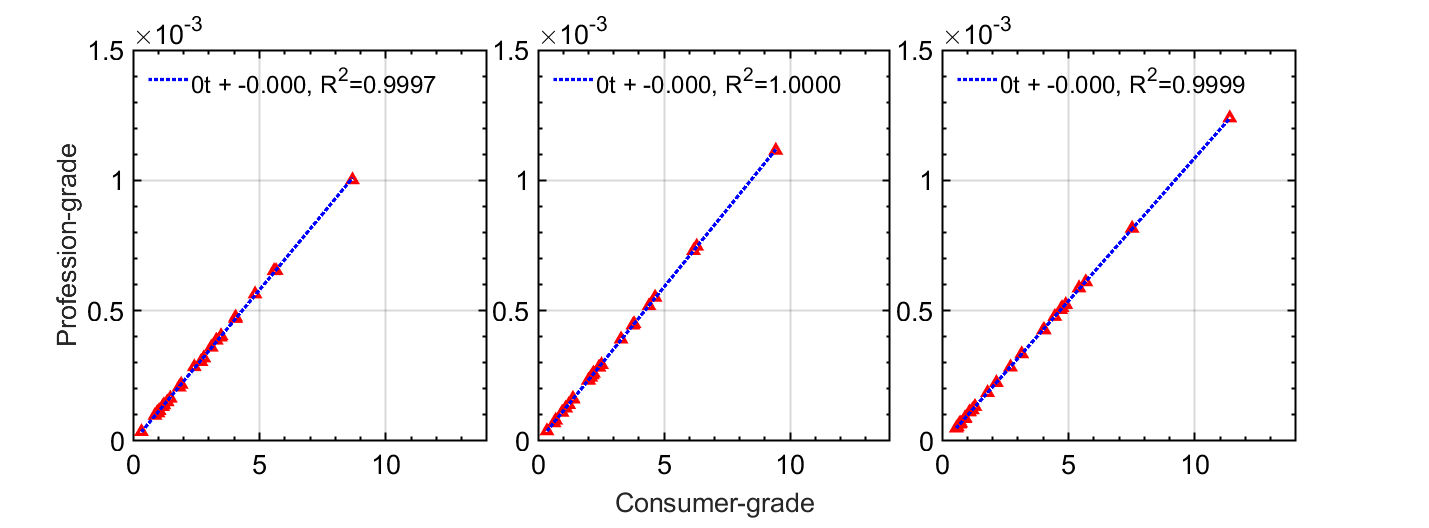

regression_data_inverse = {};

for mode = 1:4

    clf
    hfig = gcf;
    set(hfig,'Visible','on')
    td = tiledlayout(1,3,'TileSpacing',"compact");

    i = 1;
    haxis = nexttile(i);
    [poly, rsq, yfit] = linearity_analyzer(XYZ_cck{mode}(:,i),XYZ_ol490(:,i));
    regression_data_inverse{mode,i} = {poly, rsq, yfit};
    axis([0 14 0 1.5e-3])
    PlotBeautify(gca)

    i = 2;
    haxis = nexttile(i);
    [poly, rsq, yfit] = linearity_analyzer(XYZ_cck{mode}(:,i),XYZ_ol490(:,i));
    regression_data_inverse{mode,i} = {poly, rsq, yfit};
    axis([0 14 0 1.5e-3])
    PlotBeautify(gca)

    i = 3;
    haxis = nexttile(i);
    [poly, rsq, yfit] = linearity_analyzer(XYZ_cck{mode}(:,i),XYZ_ol490(:,i));
    regression_data_inverse{mode,i} = {poly, rsq, yfit};
    axis([0 14 0 1.5e-3])
    PlotBeautify(gca)

    td.YLabel.String = 'Profession-grade';
    td.YLabel.FontSize = 20;

    td.XLabel.String = 'Consumer-grade';
    td.XLabel.FontSize = 20;

    hfig.Position = [568 351 1429 528];
    saveas(hfig,sprintf('linearity_plots_inverse_mode%d.png',mode))

end


regression_data_inverse

regression_data_inverse = 4×3 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}
    {1×3 cell}    {1×3 cell}    {1×3 cell}
    {1×3 cell}    {1×3 cell}    {1×3 cell}
    {1×3 cell}    {1×3 cell}    {1×3 cell}


## How to calibrate CCK?

XYZ_cck_calibrated = XYZ_cck;

for mode = 1:4
    for ch = 1:3
        x = XYZ_cck{mode}(:,ch);
        poly = regression_data_inverse{mode,ch}{1};
        y = polyval(poly,x);
        %
        % scale up by 8500
        %
        XYZ_cck_calibrated{mode}(:,ch) = y * 8500;
    end
end

%
% write into a file
%
spyder_calibrated = zeros(24,12);

for mode = 1:4

    colstart = (mode-1)*3 + 1;
    spyder_calibrated(:,colstart:colstart+2) = XYZ_cck_calibrated{mode};

end

save('spyder_rift_calibrated.mat','spyder_calibrated')
spyder_calibrated

spyder_calibrated =     1.1633    1.0738    0.7303    1.1685    1.0661    0.7317    1.1653    1.0802    0.7336    1.1772    1.0770    0.7351
    3.9817    3.8089    2.8452    3.9745    3.8023    2.8374    3.9725    3.8057    2.8412    3.9903    3.8201    2.8399
    1.7718    1.9892    4.0682    1.7760    1.9974    4.0864    1.7886    2.0005    4.0651    1.7755    1.9853    4.0614
    0.9217    1.3700    0.7396    0.9270    1.3720    0.7442    0.9183    1.3735    0.7448    0.9162    1.3683    0.7463
    2.6249    2.5169    5.2193    2.6076    2.5090    5.1978    2.6291    2.5125    5.2120    2.6319    2.5143    5.2072
    2.7734    4.4530    4.9947    2.7567    4.4306    4.9841    2.7408    4.4094    4.9607    2.7410    4.4199    4.9560
    3.9933    3.2941    0.4626    4.0111    3.2965    0.4653    3.9982    3.2977    0.4620    3.9883    3.2972    0.4652
    1.4166    1.1981    4.4744    1.4036    1.1954    4.4548    1.4270    1.1981    4.4703    1.4282    1.1984    4.4657
    3.2257  

### Try the calibration results

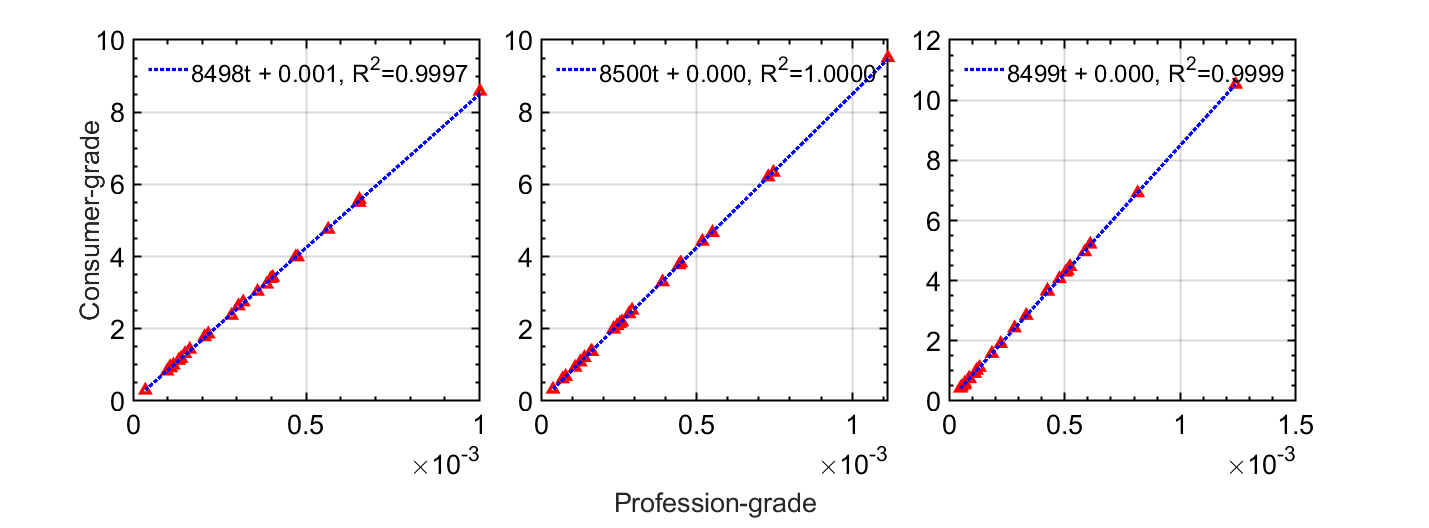

for mode = 1:4

    clf
    hfig = gcf;
    set(hfig,'Visible','on')
    td = tiledlayout(1,3,'TileSpacing',"compact");

    i = 1;
    haxis = nexttile(i);
    [poly, rsq, yfit] = linearity_analyzer(XYZ_ol490(:,i),XYZ_cck_calibrated{mode}(:,i));
    %regression_data{mode,i} = {poly, rsq, yfit};
    %axis([0 1.5e-3 0 14])
    PlotBeautify(gca)

    i = 2;
    haxis = nexttile(i);
    [poly, rsq, yfit] = linearity_analyzer(XYZ_ol490(:,i),XYZ_cck_calibrated{mode}(:,i));
    %regression_data{mode,i} = {poly, rsq, yfit};
    %axis([0 1.5e-3 0 14])
    PlotBeautify(gca)

    i = 3;
    haxis = nexttile(i);
    [poly, rsq, yfit] = linearity_analyzer(XYZ_ol490(:,i),XYZ_cck_calibrated{mode}(:,i));
    %regression_data{mode,i} = {poly, rsq, yfit};
    %axis([0 1.5e-3 0 14])
    PlotBeautify(gca)

    td.XLabel.String = 'Profession-grade';
    td.XLabel.FontSize = 20;

    td.YLabel.String = 'Consumer-grade';
    td.YLabel.FontSize = 20;

    hfig.Position = [568 351 1429 528];
    saveas(hfig,sprintf('linearity_plots_calibrated_mode%d.png',mode))

end

### Calculate LAB

LAB_cck_calibrated = {};

for mode = 1:4

    LAB_cck_calibrated{mode} = ColorConversionClass.XYZ2lab(XYZ_cck_calibrated{mode},XYZ_cck_calibrated{mode}(19,:));

end

XYZ_cck_calibrated

XYZ_cck_calibrated = 1×4 cell array
    {24×3 double}    {24×3 double}    {24×3 double}    {24×3 double}


LAB_cck_calibrated

LAB_cck_calibrated = 1×4 cell array
    {24×3 double}    {24×3 double}    {24×3 double}    {24×3 double}


### Calculate dE after calibration

dEall_calibrated = zeros(4,24);

for mode = 1:4
    for i = 1:24
        [dE00 dE94 dEab] = ColorConversionClass.LAB2dE(LAB_cck_calibrated{mode}(i,:)',LAB_ol490(i,:)');
        dE(i) = dE00;
    end
    dEall_calibrated(mode,:) = dE;
end

dEall_calibrated

dEall_calibrated =     1.0477    0.3094    0.1506    0.4652    0.2451    0.4395    0.4268    0.2213    0.5543    0.3758    0.3141    0.3181    0.7400    0.1995    0.8394    0.5229    0.4835    0.3754         0    0.5446    0.7121    0.4241    1.3765    1.2428
    0.3350    0.2721    0.1692    0.2693    0.1770    0.4479    0.3277    0.1318    0.4321    0.4339    0.4599    0.2725    0.5338    0.2378    0.6037    0.2137    0.4150    0.2187         0    0.2408    0.2408    0.2107    1.1753    0.7763
    1.3774    0.4835    0.2911    0.7158    0.1932    0.3612    0.5009    0.5416    0.5230    0.2835    0.3540    0.6484    0.3948    0.2148    0.6877    0.7675    0.4190    0.4077         0    0.3000    0.2985    0.5947    1.6877    1.7113
    0.5342    0.4148    0.1820    0.6806    0.2828    0.2764    0.6115    0.6102    0.5247    0.2522    0.3228    0.5614    0.4279    0.2122    0.5975    0.8318    0.3450    0.3909         0    0.1560    0.1682    0.4564    1.6242    1.4914


dEmean_calibrated = mean(dEall_calibrated,2)

dEmean_calibrated =     0.5137
    0.3581
    0.5732
    0.4981


## Draw a subplot

function linearity_plot (haxis,x,y,p,rsq,yfit,til)
hold on
plot(x, y,'^r');
plot(x, yfit,'b:', 'LineWidth', 1.0);
grid on
title(til)
axis([0 1.5e-3 0 14])
PlotBeautify(haxis)
legend('',sprintf('%.0ft + %.3f, R^{2}=%.4f',p(1),p(2),rsq))
end

## Find linear regression

function [p,rsq,yfit] = my_linear_reg (x, y)
p = polyfit(x,y,1);
yfit = polyval(p,x);
yresid = y - yfit;
SSresid = sum(yresid.^2);
SStotal = (length(y)-1) * var(y);
rsq = 1 - SSresid/SStotal;
end